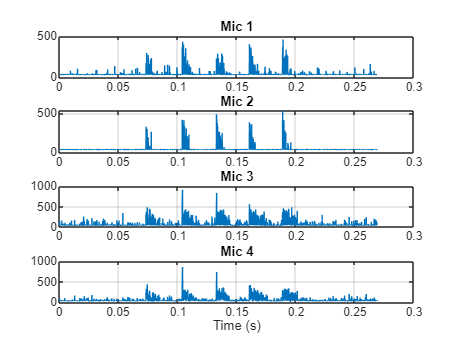

clc; clear; close all;

% Load CSV
data = readmatrix('demo_sui5.csv');

mic1 = data(:,1);
mic2 = data(:,2);
mic3 = data(:,3);
mic4 = data(:,4);

Fs = 16000;              % Sampling frequency (Hz)
Ts = 1/Fs;               % Sampling period
N = length(mic1);        % Number of samples
t = (0:N-1)*Ts;          % Time vector

figure;

subplot(4,1,1);
plot(t, mic1);
title('Mic 1'); grid on;

subplot(4,1,2);
plot(t, mic2);
title('Mic 2'); grid on;

subplot(4,1,3);
plot(t, mic3);
title('Mic 3'); grid on;

subplot(4,1,4);
plot(t, mic4);
title('Mic 4'); grid on;

xlabel('Time (s)');

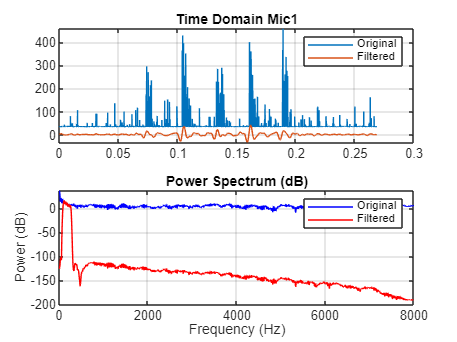

% Filter
mic1_f = bandpass(mic1, [85 250], Fs);
mic2_f = bandpass(mic2, [85 250], Fs);
mic3_f = bandpass(mic3, [85 250], Fs);
mic4_f = bandpass(mic4, [85 250], Fs);

% Mic 1
figure;
subplot(2,1,1);
plot(t, mic1); hold on;
plot(t, mic1_f);
title('Time Domain Mic1');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po1,fo1] = pspectrum(mic1, Fs);
[pf1,ff1] = pspectrum(mic1_f, Fs);

plot(fo1, 10*log10(po1), 'b'); hold on;
plot(ff1, 10*log10(pf1), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

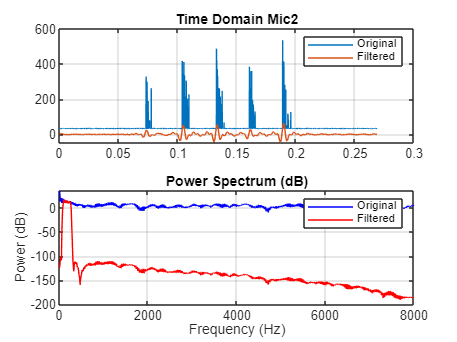


% Mic 2
figure;
subplot(2,1,1);
plot(t, mic2); hold on;
plot(t, mic2_f);
title('Time Domain Mic2');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po2,fo2] = pspectrum(mic2, Fs);
[pf2,ff2] = pspectrum(mic2_f, Fs);

plot(fo2, 10*log10(po2), 'b'); hold on;
plot(ff2, 10*log10(pf2), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

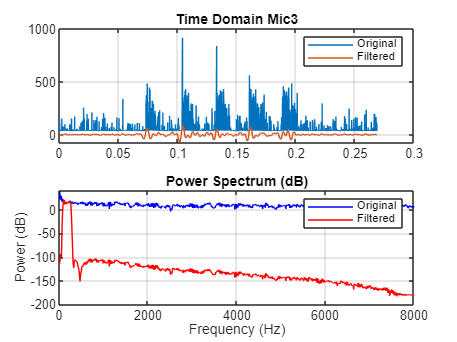


% Mic 3
figure;
subplot(2,1,1);
plot(t, mic3); hold on;
plot(t, mic3_f);
title('Time Domain Mic3');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po3,fo3] = pspectrum(mic3, Fs);
[pf3,ff3] = pspectrum(mic3_f, Fs);

plot(fo3, 10*log10(po3), 'b'); hold on;
plot(ff3, 10*log10(pf3), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

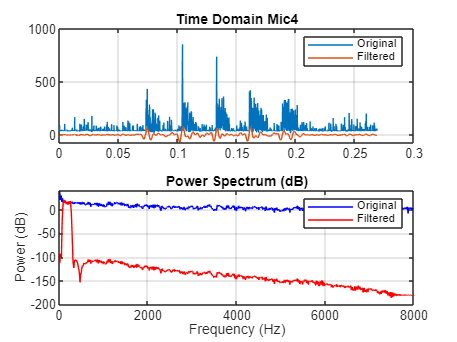


% Mic 4
figure;
subplot(2,1,1);
plot(t, mic4); hold on;
plot(t, mic4_f);
title('Time Domain Mic4');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po4,fo4] = pspectrum(mic4, Fs);
[pf4,ff4] = pspectrum(mic4_f, Fs);

plot(fo4, 10*log10(po4), 'b'); hold on;
plot(ff4, 10*log10(pf4), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

% Voice Activity Detection

ambient = readmatrix('ambient.csv');
amb1 = ambient(:,1);
amb2 = ambient(:,2);
amb3 = ambient(:,3);
amb4 = ambient(:,4);

amb1_f = bandpass(amb1, [85 250], Fs);
amb2_f = bandpass(amb2, [85 250], Fs);
amb3_f = bandpass(amb3, [85 250], Fs);
amb4_f = bandpass(amb4, [85 250], Fs);

window = 500;   % adjust based on Fs
energy_amb = movmean(amb2_f.^2, window);
energy_mic = movmean(mic1_f.^2, window);

threshold = mean(energy_mic) * 1; % fix to mean energy_mic
active_idx = energy_mic > threshold;

edges = diff([0; active_idx; 0]);

starts = find(edges == 1);
ends = find(edges == -1) - 1; % Subtract 1 to correct for the diff shift

num_snaps = length(starts)

num_snaps = 1

Snap 1: Index 1387 to 3232


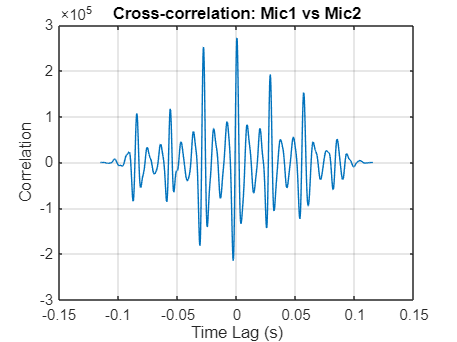

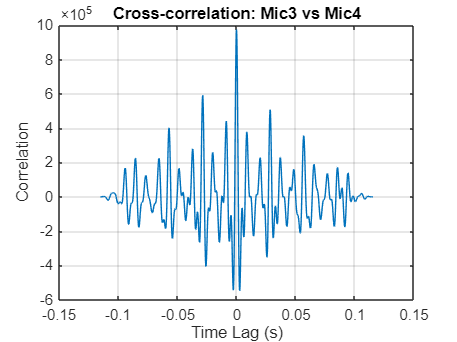

Delay Mic1-Mic2: 0.000313 s


Delay Mic3-Mic4: -0.000063 s


val12 = 0.3573

phi1 = 69.0660

val34 = -0.0715

phi2 = 94.0978


% Process each snap individually
for i = 1:num_snaps
    s_idx = starts(i);
    e_idx = ends(i);
    
    fprintf('Snap %d: Index %d to %d\n', i, s_idx, e_idx);

    mic1_ac = mic1_f(s_idx : e_idx);
    mic2_ac = mic2_f(s_idx : e_idx);
    mic3_ac = mic3_f(s_idx : e_idx);
    mic4_ac = mic4_f(s_idx : e_idx);
    
    % Cross-correlation

    % Mic 1&2
    [xc12, lags12] = xcorr(mic1_ac, mic2_ac);

    [~, idx12] = max(abs(xc12));
    lag12 = lags12(idx12);
    delay12 = lag12 / Fs;

    figure;
    plot(lags12/Fs, xc12);
    xlabel('Time Lag (s)');
    ylabel('Correlation');
    title('Cross-correlation: Mic1 vs Mic2');
    grid on;
    
    % Mic 3&4
    [xc34, lags34] = xcorr(mic3_ac, mic4_ac);
    
    [~, idx34] = max(abs(xc34));
    lag34 = lags34(idx34);
    delay34 = lag34 / Fs;
    
    figure;
    plot(lags34/Fs, xc34);
    xlabel('Time Lag (s)');
    ylabel('Correlation');
    title('Cross-correlation: Mic3 vs Mic4');
    grid on;
    
    fprintf('Delay Mic1-Mic2: %.6f s\n', delay12);
    fprintf('Delay Mic3-Mic4: %.6f s\n', delay34);
    
    c = 343;
    d = 0.3;
    val12 = (c * delay12) / d
    phi1 = rad2deg(acos(val12))
    
    val34 = (c * delay34) / d
    phi2 = rad2deg(acos(val34))
end

% % Detect Speech
% clf;
% figure;
% [idx,thresholds] = detectSpeech(mic1_f, Fs)
% 
% detectSpeech(mic1_f, Fs,'Thresholds',thresholds)
% 
% mic1_f = mic1_f(idx(1,1):idx(1,2));
% mic2_f = mic2_f(idx(1,1):idx(1,2));
% mic3_f = mic3_f(idx(1,1):idx(1,2));
% mic4_f = mic4_f(idx(1,1):idx(1,2));
% 
% fprintf('Segment : %d to %d\n', idx(1,1), idx(1,2));

% % Cross-correlation
% 
% % Mic 1&2
% [xc12, lags12] = xcorr(mic1_ac, mic2_ac);
% 
% [~, idx12] = max(abs(xc12));
% lag12 = lags12(idx12);
% delay12 = lag12 / Fs;
% 
% figure;
% plot(lags12/Fs, xc12);
% xlabel('Time Lag (s)');
% ylabel('Correlation');
% title('Cross-correlation: Mic1 vs Mic2');
% grid on;
% 
% % Mic 3&4
% [xc34, lags34] = xcorr(mic3_ac, mic4_ac);
% 
% [~, idx34] = max(abs(xc34));
% lag34 = lags34(idx34);
% delay34 = lag34 / Fs;
% 
% figure;
% plot(lags34/Fs, xc34);
% xlabel('Time Lag (s)');
% ylabel('Correlation');
% title('Cross-correlation: Mic3 vs Mic4');
% grid on;
% 
% fprintf('Delay Mic1-Mic2: %.6f s\n', delay12);
% fprintf('Delay Mic3-Mic4: %.6f s\n', delay34);
% 
% c = 343;
% d = 0.3;
% val12 = (c * delay12) / d
% phi1 = rad2deg(acos(val12))
% 
% val34 = (c * delay34) / d
% phi2 = rad2deg(acos(val34))

% c = 343;
% d = 0.3; % The spacing between adjacent microphones
% 
% % ==========================================
% % MIC 1 COMBINATIONS
% % ==========================================
% 
% % Mic 1 vs 2 (Distance = 1*d)
% [xc12, lags12] = xcorr(mic1_ac, mic2_ac);
% [~, idx12] = max(abs(xc12));
% delay12 = lags12(idx12) / Fs;
% val12 = (c * delay12) / d;
% 
% % Mic 1 vs 3 (Distance = 2*d)
% [xc13, lags13] = xcorr(mic1_ac, mic3_ac);
% [~, idx13] = max(abs(xc13));
% delay13 = lags13(idx13) / Fs;
% val13 = (c * delay13) / (2 * d);
% 
% % Mic 1 vs 4 (Distance = 3*d)
% [xc14, lags14] = xcorr(mic1_ac, mic4_ac);
% [~, idx14] = max(abs(xc14));
% delay14 = lags14(idx14) / Fs;
% val14 = (c * delay14) / (3 * d);
% 
% % Average the values instead of the time delays
% val1_avg = (val12 + val13 + val14) / 3;
% fprintf('Avg Val Mic1 combinations: %.6f\n', val1_avg);
% 
% val1_avg = max(min(val1_avg, 1), -1);   % clamp to [-1,1]
% phi1 = rad2deg(acos(val1_avg))
% 
% 
% % ==========================================
% % MIC 2 COMBINATIONS
% % ==========================================
% 
% % Mic 2 vs 1 (Distance = 1*d)
% [xc21, lags21] = xcorr(mic2_ac, mic1_ac);
% [~, idx21] = max(abs(xc21));
% delay21 = lags21(idx21) / Fs;
% val21 = (c * delay21) / d;
% 
% % Mic 2 vs 3 (Distance = 1*d)
% [xc23, lags23] = xcorr(mic2_ac, mic3_ac);
% [~, idx23] = max(abs(xc23));
% delay23 = lags23(idx23) / Fs;
% val23 = (c * delay23) / d;
% 
% % Mic 2 vs 4 (Distance = 2*d)
% [xc24, lags24] = xcorr(mic2_ac, mic4_ac); % Fixed copy-paste bug here
% [~, idx24] = max(abs(xc24));
% delay24 = lags24(idx24) / Fs;
% val24 = (c * delay24) / (2 * d);
% 
% % Average the values
% val2_avg = (val21 + val23 + val24) / 3;
% fprintf('Avg Val Mic2 combinations: %.6f\n', val2_avg);
% 
% val2_avg = max(min(val2_avg, 1), -1);   % clamp to [-1,1]
% phi2 = rad2deg(acos(val2_avg))

% L = 0.3;
% c = 343;
% 
% %delay12
% val12 = c *  delay12 / L;
% fprintf('Val Mic1-Mic2: %.6f s\n', val12);
% val12 = max(min(val12, 1), -1);   % clamp to [-1,1]
% 
% %delay34
% val34 = c * delay34 / L;
% fprintf('Val Mic-Mic4: %.6f s\n', val34);
% val34 = max(min(val34, 1), -1);   % clamp to [-1,1]
% 
% phi12 = rad2deg(acos(val12))
% phi34 = rad2deg(acos(val34))
% % phi12 = rad2deg(asin(c*delay12/L))